% clear ;

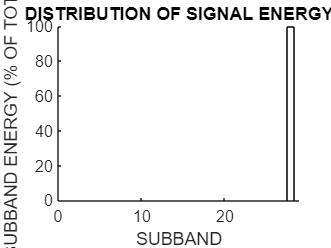

    
     %process complete signal to check for sustained oscillation dominated
     %frequency for complete test duration
     % 1024 samples best suited for our case where 1512 samples taken for 152 seconds test duration
                r1=3;
                J1=27;
                x_sig=x_phase(128:1151,1); % tested and this number is fixed as optimum for finding data analysis for signal capture 
                [y1,y2,w1,Q1] = myemd(x_sig);

e = 1.0e+04 *

    0.0001    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0001    0.0001    0.0006    0.0001    0.0001    0.0000    0.0002    0.0002    0.0001    0.0001    0.0005    0.0010    0.0006    0.0003    0.0007    0.0000    1.6143


                % energy in each sub-band (J=27)
                e=PlotEnergy(w1)

                fs=10;
                if Q1<5
                    J1=22;
                end
                % Center freq of each sub-band
                fc=tqwt_fc(Q1,r1,J1,fs);
                % store centre freq and its energy in matrix hr_test
                hr_test=zeros(2,J1);
                hr_test(1,:)=fc;
                hr_test(2,:)=e(1,1:J1);
                %find out the HR indices fundamental
                % frequency sorted based on the sub-band energy 
                % frequencies arranged in descending order
                hr_test_1=hr_test(:,(hr_test(1,:)>1));
                hr_test_1=hr_test_1(:,(hr_test_1(1,:)<1.65))

hr_test_1 =     1.6391    1.5563    1.4777    1.4031    1.3322    1.2649    1.2011
    1.1394    4.6822   10.1284    6.0360    3.2830    7.1912    0.2930


                [~,esort]=sort(hr_test_1(2,:),'descend');
                fc_hr_1=hr_test_1(1,esort);
                
                % find out the HR indices first harmonic range 
                hr_test_2=hr_test(:,(hr_test(1,:)>2.015));
                hr_test_2=hr_test_2(:,(hr_test_2(1,:)<3.3));
                [~,esort]=sort(hr_test_2(2,:),'descend');
                fc_hr_2=hr_test_2(1,esort)

fc_hr_2 =     2.3559    2.2369    2.1240    2.8986    2.4812    2.6132    2.0167    3.2152    2.7522    3.0528


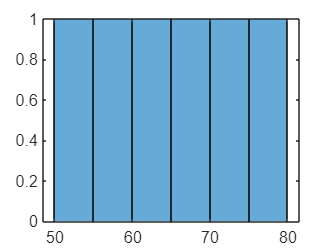

                
                % freq padding if atleast three frequencies are not available 
                if length(fc_hr_1)==2
                    fc_hr_1(3)=fc_hr_1(1);
                elseif length(fc_hr_1)==1
                    fc_hr_1(2)=fc_hr_1(1);
                    fc_hr_1(3)=fc_hr_1(1);
                end
                if length(fc_hr_2)==2
                    fc_hr_2(3)=fc_hr_2(1);
                elseif length(fc_hr_2)==1
                    fc_hr_2(2)=fc_hr_2(1);
                    fc_hr_2(3)=fc_hr_2(1);
                end
                if isempty(fc_hr_1)
                    fc_hr_1=fc_hr_2./2;
                end
                
                x_heart_radar_1=round(fc_hr_1(1:3),2);
                % factor 51.2 = 512 pt FFT=10 Hz sampling rate
                x_heart_radar_index1=round(x_heart_radar_1.*51.2);
                x_heart_radar_2=round(fc_hr_2(1:3),2);
                x_heart_radar_index2=round(x_heart_radar_2.*51.2/2);
                index_hr(1,1:3)=x_heart_radar_index1;
                index_hr(1,4:6)=x_heart_radar_index2;
                %Find the best representative of frequency in the basic and
                %first harmonic top three enrgy values
                h=histogram(index_hr(1,:),'BinWidth',5);

                [~,idxh]=sort(h.Values,'descend');
                index_radar=h.BinEdges(idxh(1))+3;%center of histogram width
               
               

## HR harmonic values id estimation through RSSD

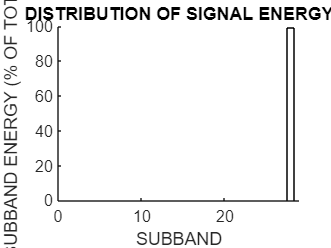

    ix0=round(60*512/(fs*60))+3;
    Nr=length(x_phase); %% 
    Nchirp=512;  %% equivalent to 512*100msec = 52sec
    init_chirp = 1;
    est_window=10; %% equivalent to 10*100msec= 1sec
    noofestimates = round((Nr - Nchirp)/est_window);
    ihh=zeros(noofestimates,6);
    for p = 1:noofestimates
        end_chirp = init_chirp+Nchirp-1;
        x_sig=x_phase(init_chirp:end_chirp);
        init_chirp= p*est_window +1;
        [y1,y2,w1] = myemd_sec(x_sig,Q1);
                e=PlotEnergy(w1);
                fc=tqwt_fc(Q1,r1,J1,fs);
                hr_test=zeros(2,J1);
                hr_test(1,:)=fc;
                hr_test(2,:)=e(1,1:J1);
                %find out the HR indices fundamental
                hr_test_1=hr_test(:,(hr_test(1,:)>1));
                hr_test_1=hr_test_1(:,(hr_test_1(1,:)<1.65));
                [~,esort]=sort(hr_test_1(2,:),'descend');
                fc_hr_1=hr_test_1(1,esort);
                
                %first harmonic range check index
                hr_test_2=hr_test(:,(hr_test(1,:)>2.015));
                hr_test_2=hr_test_2(:,(hr_test_2(1,:)<3.3));
                [~,esort]=sort(hr_test_2(2,:),'descend');
                fc_hr_2=hr_test_2(1,esort);
                if length(fc_hr_1)==2
                    fc_hr_1(3)=fc_hr_1(1);
                elseif length(fc_hr_1)==1
                    fc_hr_1(2)=fc_hr_1(1);
                    fc_hr_1(3)=fc_hr_1(1);
                end
                if length(fc_hr_2)==2
                    fc_hr_2(3)=fc_hr_2(1);
                elseif length(fc_hr_2)==1
                    fc_hr_2(2)=fc_hr_2(1);
                    fc_hr_2(3)=fc_hr_2(1);
                end
                if isempty(fc_hr_1)
                    fc_hr_1=fc_hr_2;
                end
                
                x_heart_radar_1=round(fc_hr_1(1:3),2);
                x_heart_radar_index1=round(x_heart_radar_1.*51.2);
                x_heart_radar_2=round(fc_hr_2(1:3),2);
                x_heart_radar_index2=round(x_heart_radar_2.*51.2/2);
                ihh(p,1:3)=x_heart_radar_index1;
                ihh(p,4:6)=x_heart_radar_index2;
    end

    %write all hr index in a file
    % noofestimates=100;
    x_heart = readmatrix("C:\Users\Anuradha\Desktop\RA_Maori Vital Sign Study\Data Collection Folder\Participant 1\HR_Hex_Data.xlsx")

x_heart =     86    83    85    88    86    84    82    90
    86    84    85    88    85    84    82    90
    87    84    84    87    84    83    83    90
    86    84    84    87    84    81    83    89
    85    84    84    85    85    81    84    89
    85    85    84    85    86    82    84    89
    86    85    84    84    86    82    85    87
    87    84    84    84    85    81    85    86
    87    84    84    85    85    81    85    86
    86    83    85    85    85    81    85    85


    hr_hex=x_heart(13:12+noofestimates,6);
    hr_hex_ind=round(hr_hex*512/600);
    hr_ind_cpm=ihh;
    hr_ind_cpm(:,7)=index_radar;
    hr_ind_cpm(:,8)=hr_hex_ind;
%     f2 = fullfile(filepath,"hr_radar_index.xlsx");
%     writematrix(hr_ind_cpm,f2);

